Antoine BERTRAND - 2024/2025

## H2 Engine simulation : 3D ConvergeCFD simulation to 1D GTPower model

The workflow is the following :

**        I. Compute MFB from H₂ mass fraction**

        ├─► Open the species_mass_region_0.out file of the simulation

        ├─► Export into a species_mass_case_#.txt file the following parameters : Crank(deg); Mass_H2(kg); Mass_O2(kg); Mass_H2O(kg); Mass_OH(kg)

        └─► Select the Start of Combustion and End of Combustion based on the case

**        II. Convert Species Mass into Mass Fraction Burned (MFB)**

        ├─► The MFB curve need to be monotonic, positive and not exceed 1000 pts

        └─► The MFB curve is exported to MFB_case_#.txt

**        III. Interpolation of the MFB curves**

        ├─► Based on the MFB_case_#.txt file an interpolation is made to extend the number of cases

        └─► The MFB curves are transferred to a GTPower combustion_profile module

        **IV. GTPower performance outputs**

        ├─► Run the cases on GTPower

        └─► Import all the following parameters Brake Power (kW)  Brake Torque (Nm)  Brake Efficiency (%)  CA50 knock probability into a Perf.txt file

## **        I. Compute MFB from H₂ mass fraction**

clearvars;
close all;
clc;

This section is about converting a Species Mass table from the ConvergeCFD simulation into Mass Fraction Burned table for the GTPower model.

Note : The output files from ConvergeCFD must be filtered to be accepted as a GTPower inputs file, that is why an interpolation is needed to not exceed 1000 points

% Select case
scriptFolder = pwd;
CasesPath = fullfile(scriptFolder, 'data', 'Cases.txt');
Cases = readtable(CasesPath, 'Delimiter', '	', 'PreserveVariableNames', true);
Cases.Properties.VariableNames{1} = 'CaseID';

row = Cases(Cases.Phi == 0.6 & Cases.SOC == 10, :);
case_number = row.CaseID;

% Load the data
filename = sprintf('species_mass_case_%d.txt', case_number)

filename = 'species_mass_case_2.txt'

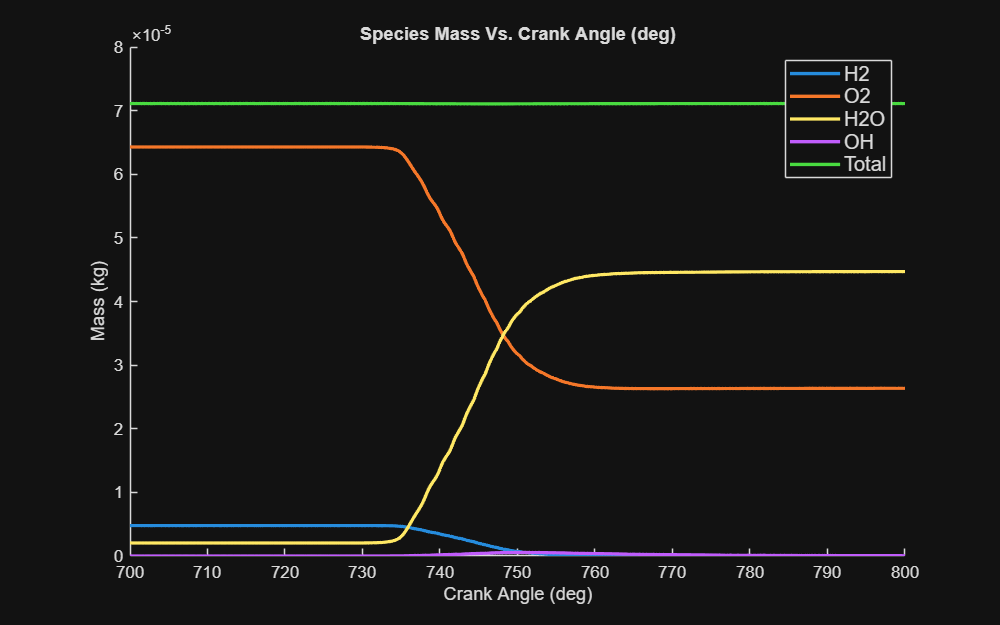

FilePath = fullfile(scriptFolder, 'data', filename);
data = readtable(FilePath, 'Delimiter', '	', 'PreserveVariableNames', true,'HeaderLines', 6);

% Parameters
CrankStart = 700;
CrankEnd = 800;

% Plot the species mass graph
figure('Position', [100, 100, 800, 500]);
hold on
plot(data.("Crank(deg)"), data.("Mass_H2(kg)"), 'LineWidth', 2);
plot(data.("Crank(deg)"), data.("Mass_O2(kg)"), 'LineWidth', 2);
plot(data.("Crank(deg)"), data.("Mass_H2O(kg)"), 'LineWidth', 2);
plot(data.("Crank(deg)"), data.("Mass_OH(kg)"), 'LineWidth', 2);
plot(data.("Crank(deg)"), data.("Mass_OH(kg)")+data.("Mass_O2(kg)")+data.("Mass_H2(kg)")+data.("Mass_H2O(kg)"), 'LineWidth', 2);
xlabel('Crank Angle (deg)');
ylabel('Mass (kg)');
title('Species Mass Vs. Crank Angle (deg)');
legend({'H2', 'O2', 'H2O','OH','Total'}, 'Location', 'northeast', 'FontSize', 12);
xlim([CrankStart CrankEnd]);

## **        II. Convert Species Mass into Mass Fraction Burned (MFB)**

This section convert the Species Mass into MFB by interpolating the H₂ curve over a defined number of points. Also making sure the MFB curve is monotonic and positive

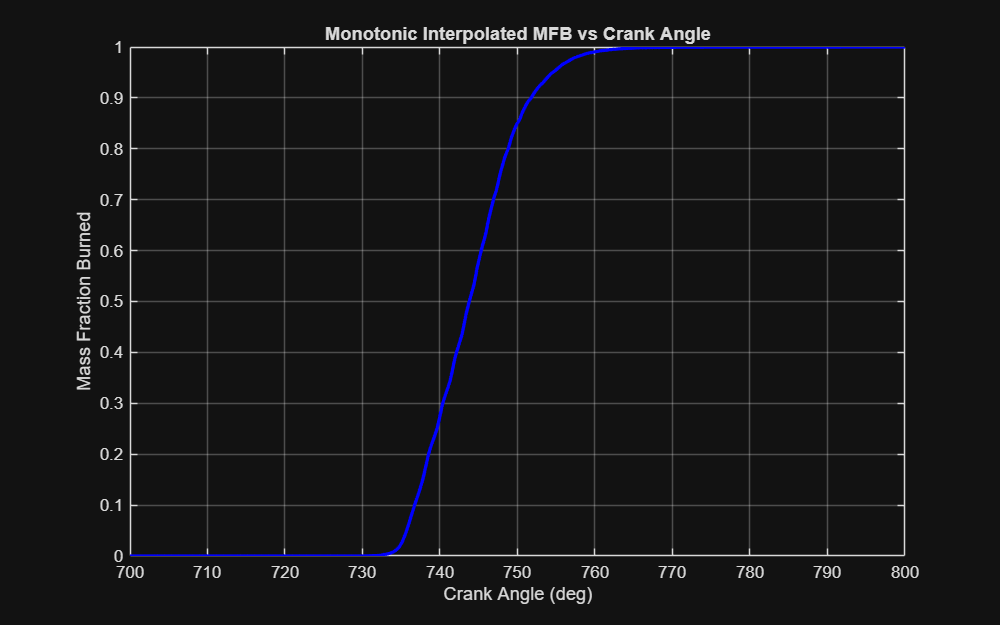

% MFB parameters
N = 1000;

% Filtering datas in the desired range
mask = (data.("Crank(deg)") >= CrankStart) & (data.("Crank(deg)") <= CrankEnd);
crank_range = data.("Crank(deg)")(mask);
mass_H2 = data.("Mass_H2(kg)")(mask);

mass_H2_initial = mass_H2(1);

% MFB Calculation
MFB = (mass_H2_initial - mass_H2) / mass_H2_initial;

% Making sure the MFB is monotone increasing
MFB_monotone = MFB;
for i = 2:length(MFB_monotone)
    if MFB_monotone(i) < MFB_monotone(i-1)
        MFB_monotone(i) = MFB_monotone(i-1);
    end
end

% Interpolation
crank_interp = linspace(CrankStart, CrankEnd, N);
MFB_interp = interp1(crank_range, MFB_monotone, crank_interp, 'linear', 'extrap');

MFB_new1 = max(MFB_interp, 0);

% Plot the MFB graph
figure('Position', [100, 100, 800, 500]);
plot(crank_interp, MFB_new1, 'b-', 'LineWidth', 2);
xlabel('Crank Angle (deg)');
ylabel('Mass Fraction Burned');
title('Monotonic Interpolated MFB vs Crank Angle');
grid on;

This section export the MFB curve into a .txt file for GTPower

All the file starts at CA = 0, you have to specify in GTPower the SOC and the MFB curve will be automatically shifted.

% Writing output file
output_filename = sprintf('MFB_case_%d.txt', case_number)

output_filename = 'MFB_case_2.txt'

fid = fopen(output_filename, 'w');

fprintf(fid, 'Crank_Angle_(deg)\tMFB_(%%)\n');

for i = 1:length(crank_interp)
    fprintf(fid, '%.6f\t%.6f\n', crank_interp(i)-CrankStart, MFB_new1(i));
end

fclose(fid);

## **        III. Interpolation of the MFB curves**

This section show a 2D map of all the simulations made as a combinaison of SOC and Phi.

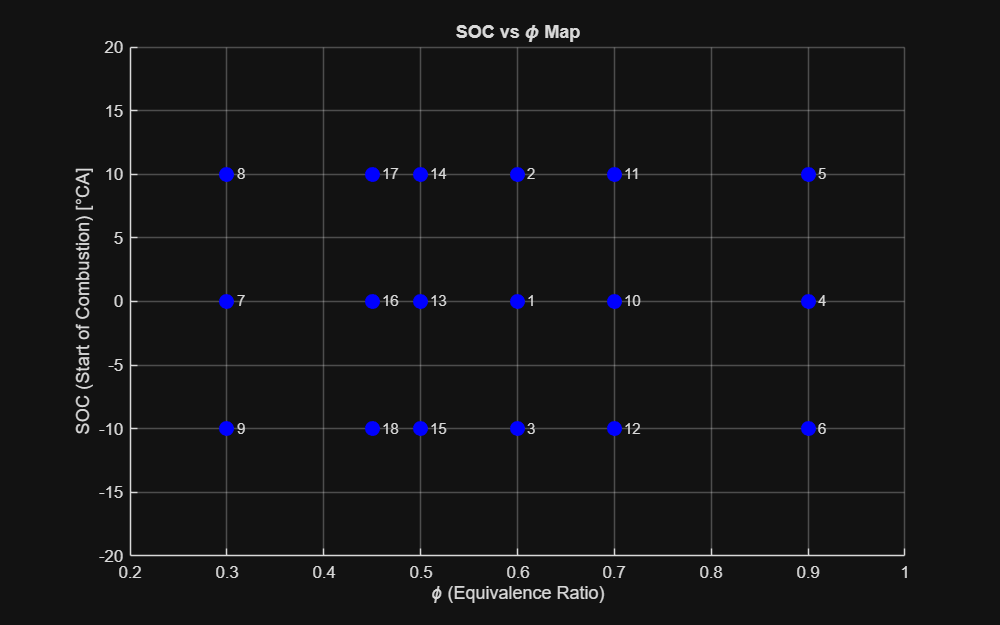

% Plot the 2D Map
figure('Position', [100, 100, 800, 500]); hold on; grid on;

% Load all the points from the Cases.txt file
scatter(Cases.Phi, Cases.SOC, 80, 'b', 'filled');
for i = 1:height(Cases)
    text(Cases.Phi(i) + 0.01, Cases.SOC(i), num2str(Cases{i,1}), 'FontSize', 9);
end
xlabel('\phi (Equivalence Ratio)');
ylabel('SOC (Start of Combustion) [°CA]');
title('SOC vs \phi Map');
xlim([0.2 1.0]);
ylim([-20 20]);

This section transform the MFB(theta) function as a continuous function of Phi for a fixed SOC

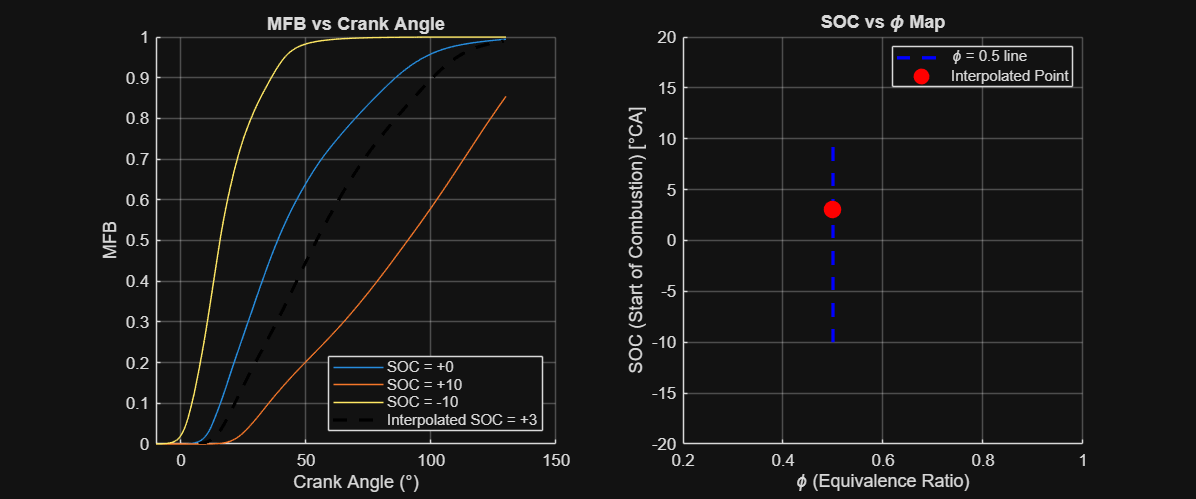

clearvars;
close all;
clc;
addpath('src');

% Load the data
scriptFolder = pwd;
CasesPath = fullfile(scriptFolder, 'data', 'Cases.txt');
Cases = readtable(CasesPath, 'Delimiter', '	', 'PreserveVariableNames', true);
Cases.Properties.VariableNames{1} = 'CaseID';

phi = 0.5;                          % Constant value of Phi
SOC_target = 3;                     % SOC that will be interpolated

row = Cases(Cases.Phi == phi, :);  % Lines where Phi stay constant
case_number = row.CaseID;

% Read the MFB files and load the corresponding SOC
MFB_all = {};
SOC_list = zeros(1, length(case_number));
for i = 1:length(case_number)
    filename = sprintf("MFB_case_%d.txt", case_number(i));
    FilePath = fullfile(scriptFolder, 'data', filename);
    MFB_all{i} = readtable(FilePath, 'Delimiter', '	', 'PreserveVariableNames', true);
    SOC_list(i) = Cases.SOC(Cases.CaseID == case_number(i));
end

[crank_target, MFB_target] = interMFB_SOC(MFB_all, SOC_target, SOC_list);

% Plot
figure('Position', [100, 100, 1200, 500]);

% First subplot : MFB vs Crank
subplot(1,2,1);
hold on;
colors = lines(length(SOC_list));
for i = 1:length(SOC_list)
    crank_plot = MFB_all{i}{:,1}-10;
    MFB_plot = MFB_all{i}{:,2};
    plot(crank_plot, MFB_plot, '-', ...
         'Color', colors(i,:), ...
         'DisplayName', sprintf('SOC = %+d', SOC_list(i)));
end
plot(crank_target, MFB_target, 'k--', 'LineWidth', 2, ...
     'DisplayName', sprintf('Interpolated SOC = %+g', SOC_target));
xlabel('Crank Angle (°)');
ylabel('MFB');
legend('Location', 'southeast');
ylim([0 1]); 
grid on;
title('MFB vs Crank Angle');

% Second subplot : SOC vs phi Map
subplot(1,2,2);
hold on; grid on;
phi_line = phi;
SOC_range = -10:1:10;
plot(phi_line * ones(size(SOC_range)), SOC_range, 'b--', 'LineWidth', 2);
plot(phi, SOC_target, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
xlabel('\phi (Equivalence Ratio)');
ylabel('SOC (Start of Combustion) [°CA]');
title('SOC vs \phi Map');
legend({'\phi = 0.5 line', 'Interpolated Point'}, 'Location', 'best');
xlim([0.2 1.0]);
ylim([-20 20]);

This section transform the MFB(theta) function as a continuous function of SOC for a fixed Phi

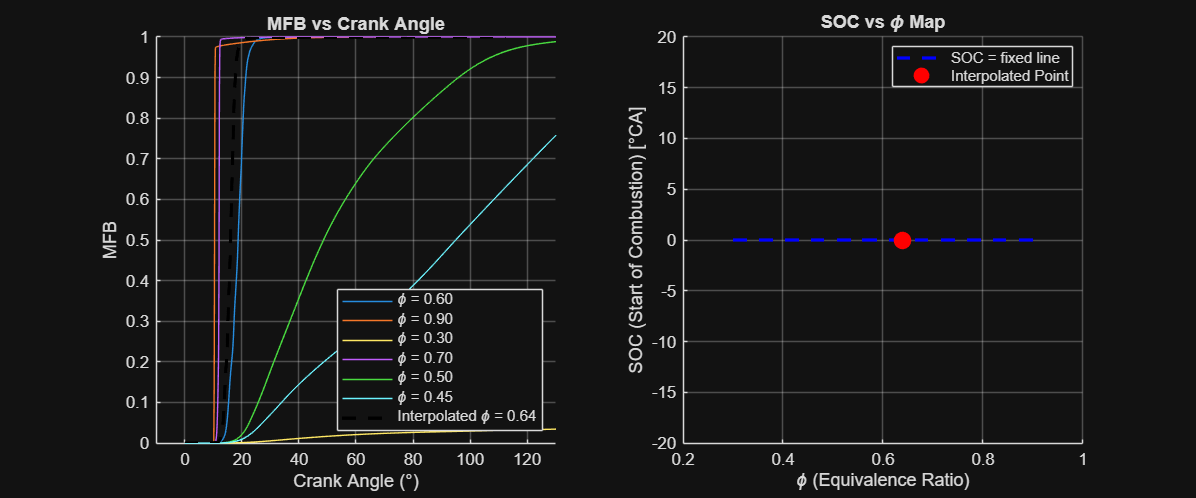

clearvars;
close all;
clc;
addpath('src');

% Load the data
scriptFolder = pwd;
CasesPath = fullfile(scriptFolder, 'data', 'Cases.txt');
Cases = readtable(CasesPath, 'Delimiter', '	', 'PreserveVariableNames', true);
Cases.Properties.VariableNames{1} = 'CaseID';

SOC = 0;                           % Constant value of SOC
phi_target = 0.64;                  % Phi that will be interpolated

% Lines where SOC stay constant
row = Cases(Cases.SOC == SOC, :);  
case_number = row.CaseID;

% Read the MFB files and load the corresponding Phi
MFB_all = {};
phi_list = zeros(1, length(case_number));
for i = 1:length(case_number)
    filename = sprintf("MFB_case_%d.txt", case_number(i));
    FilePath = fullfile(scriptFolder, 'data', filename);
    MFB_all{i} = readtable(FilePath, 'Delimiter', '	', 'PreserveVariableNames', true);
    phi_list(i) = Cases.Phi(Cases.CaseID == case_number(i));
end

[crank_target, MFB_target] = interMFB_PHI(MFB_all, phi_target, phi_list, SOC);

% Plot
figure('Position', [100, 100, 1200, 500]);

% First subplot : MFB vs Crank
subplot(1,2,1);
hold on;
colors = lines(length(phi_list));
for i = 1:length(phi_list)
    crank_plot = MFB_all{i}{:,1} + SOC;
    MFB_plot = MFB_all{i}{:,2};
    plot(crank_plot, MFB_plot, '-', ...
         'Color', colors(i,:), ...
         'DisplayName', sprintf('\\phi = %.2f', phi_list(i)));
end
plot(crank_target, MFB_target, 'k--', 'LineWidth', 2, ...
     'DisplayName', sprintf('Interpolated \\phi = %.2f', phi_target));
xlabel('Crank Angle (°)');
ylabel('MFB');
legend('Location', 'southeast');
ylim([0 1]); 
xlim([-10 130])
grid on;
title('MFB vs Crank Angle');

% Second subplot : SOC vs phi Map
subplot(1,2,2);
hold on; grid on;
phi_range = 0.3:0.01:0.9;
plot(phi_range, SOC * ones(size(phi_range)), 'b--', 'LineWidth', 2);
plot(phi_target, SOC, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
xlabel('\phi (Equivalence Ratio)');
ylabel('SOC (Start of Combustion) [°CA]');
title('SOC vs \phi Map');
legend({'SOC = fixed line', 'Interpolated Point'}, 'Location', 'best');
xlim([0.2 1.0]);
ylim([-20 20]);

Based on the simulation results, this section gives an interpolated MFB(theta) curves for each SOC and Phi

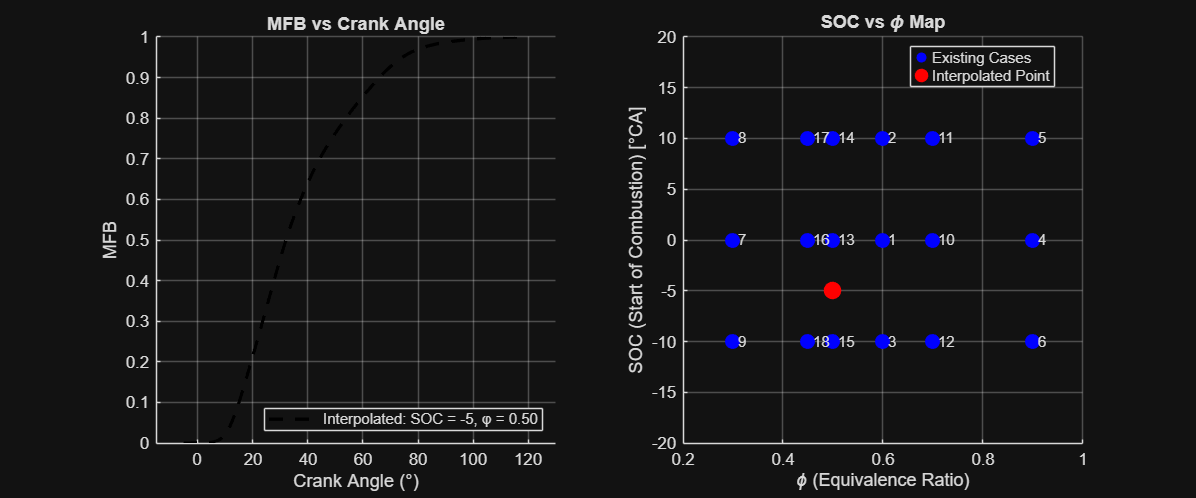

clearvars;
close all;
clc;
addpath('src');

% Wanted Parameters
SOC_target = -5;
phi_target = 0.5;

% Load the data
scriptFolder = pwd;
CasesPath = fullfile(scriptFolder, 'data', 'Cases.txt');
Cases = readtable(CasesPath, 'Delimiter', '	', 'PreserveVariableNames', true);
Cases.Properties.VariableNames{1} = 'CaseID';

% List of all the SOC simulated
SOC_list = unique(Cases.SOC)';

[crank_target, MFB_target] = interMFB_SOC_PHI(Cases, SOC_list, SOC_target, phi_target);

% Plot
figure('Position', [100, 100, 1200, 500]);

% Plot MFB vs Crank
subplot(1,2,1);
hold on;
plot(crank_target, MFB_target, 'k--', 'LineWidth', 2, ...
     'DisplayName', sprintf('Interpolated: SOC = %g, φ = %.2f', SOC_target, phi_target));
xlabel('Crank Angle (°)');
ylabel('MFB');
title('MFB vs Crank Angle');
ylim([0 1]); 
xlim([SOC_target-10 130]);
grid on;
legend('Location','southeast');

% Map SOC vs φ
subplot(1,2,2);
hold on; grid on;

scatter(Cases.Phi, Cases.SOC, 80, 'b', 'filled');
plot(phi_target, SOC_target, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
for i = 1:height(Cases)
    text(Cases.Phi(i) + 0.01, Cases.SOC(i), num2str(Cases.CaseID(i)), ...
         'FontSize', 9);
end

xlabel('\phi (Equivalence Ratio)');
ylabel('SOC (Start of Combustion) [°CA]');
title('SOC vs \phi Map');
xlim([0.2 1.0]);
ylim([-20 20]);
legend({'Existing Cases', 'Interpolated Point'}, 'Location', 'best');

Making sure the MFB is monotone increasing and positive before exporting it to the GTPower EngCylCombProfil

% Making sure the MFB is monotone increasing
MFB_monotone = MFB_target;
for i = 2:length(MFB_monotone)
    if MFB_monotone(i) < MFB_monotone(i-1)
        MFB_monotone(i) = MFB_monotone(i-1);
    end
end

MFB = max(MFB_monotone, 0);

target = 9;

% Writing output file
output_filename = sprintf('MFB_%d.txt', target)

output_filename = 'MFB_9.txt'

fid = fopen(output_filename, 'w');

fprintf(fid, 'Crank_Angle_(deg)\tMFB_(%%)\n');

for i = 1:length(crank_target)
    fprintf(fid, '%.6f\t%.6f\n', crank_target(i), MFB(i));
end

fclose(fid);

## **        IV. GTPower performance outputs**

This section interpolate for all the SOC and Phi combinaison possible (It can takes some time so the code the plot is in a different section)

clearvars;
close all;
clc;

% Load the data
scriptFolder = pwd;
CasesPath = fullfile(scriptFolder, 'data', 'Cases.txt');
Cases = readtable(CasesPath, 'Delimiter', '	', 'PreserveVariableNames', true);
Cases.Properties.VariableNames{1} = 'CaseID';

% Grids resolution
SOC_grid = -10:0.5:10;
phi_grid = 0.3:0.05:0.9;

% Initializing the result matrix
MFB_end_map = nan(length(SOC_grid), length(phi_grid)); % Z(i,j) = MFB final for SOC(i), phi(j)
MFB_CA50_map = nan(length(SOC_grid), length(phi_grid)); % Z(i,j) = MFB final for SOC(i), phi(j)

% Completing the matrix
for i = 1:length(SOC_grid)
    for j = 1:length(phi_grid)
        SOC_target = SOC_grid(i);
        phi_target = phi_grid(j);
        SOC_list = unique(Cases.SOC)';
        [crank_target, MFB_target] = interMFB_SOC_PHI(Cases, SOC_list, SOC_target, phi_target);
        MFB_end_map(i, j) = MFB_target(end);
        CA50 = interp1(MFB_target, crank_target, 0.5, 'linear');
        MFB_CA50_map(i, j) = CA50;
    end
end


SOC_grid = -10:0.5:10;
phi_grid = 0.3:0.05:0.9;
% Plot the graphs
[PHI_grid, SOC_grid] = meshgrid(phi_grid, SOC_grid);
figure('Position', [100, 100, 1600, 500]);

% Plot of the MFB_end_map
subplot(1,2,1);
surf(PHI_grid, SOC_grid, MFB_end_map);
xlabel('\phi (Equivalence Ratio)');
ylabel('SOC (°CA)');
zlabel('Fuel Fraction Burned @ 130°CA');
title('Fuel Burn Completion Map');
xlim([0.3 0.9]);
cb = colorbar;
ylabel(cb, 'Fuel Fraction Burned @ 130°CA');
view(2);
shading interp;

% Plot of the MFB_CA50_map
subplot(1,2,2);
MFB_CA50_map(isnan(MFB_CA50_map)) = 130;
surf(PHI_grid, SOC_grid, MFB_CA50_map);
shading interp;
view(2);
hold on;

% Isocurve CA50 = 10 
contour3(PHI_grid, SOC_grid, MFB_CA50_map, [10 10], ...
         'r--', 'LineWidth', 2);
Zcontour = MFB_CA50_map;
Zcontour(:) = 100;
contour3(PHI_grid, SOC_grid, Zcontour, [10 10], 'r--', 'LineWidth', 2);

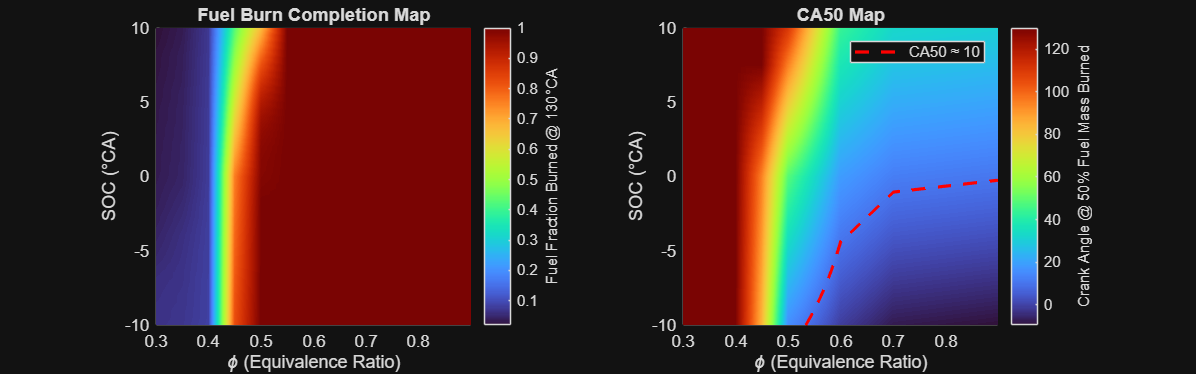


xlabel('\phi (Equivalence Ratio)');
ylabel('SOC (°CA)');
zlabel('Fuel Fraction Burned @ 130°CA');
title('CA50 Map');
cb = colorbar;
ylabel(cb, 'Crank Angle @ 50% Fuel Mass Burned');
colormap(turbo);
hFake = plot(nan, nan, 'r--', 'LineWidth', 2);
legend(hFake, 'CA50 ≈ 10');

%[x, y] = ginput(1);  % allows to clic on the graph
%disp(['Phi = ', num2str(x), ', SOC = ', num2str(y)]);